# Long-term Variant Scenario Forecasts

**[Updated Mar 29th, 2021, based on data up to Mar 27th,2021 ]**

The following scenarios have been simulated considering the combinations of the following (motivated by the [MIDAS Scenario Modeling Hub](https://github.com/midas-network/covid19-scenario-modeling-hub))

- **High Vaccination -**  Assumes 50 million courses of 2-dose vaccines administered per month in the future, and efficacy 95% after two doses, 75% after one dose. Vaccine acceptance in any priority group is around 70-90%. Additionally, 10-20M doses of J&J available with efficacy 70%.

- **Low Vaccines** - Assumes 45 million courses administered per month in the future, and efficacy 85% after two doses, 50% after one dose. Vaccine acceptance in any priority group is 50-75%.  Additionally, 5M doses of J&J available with efficacy 60%.

- **Moderate NPI** - Precautions stepped down to 50% of March levels gradually over 5 months (100% would mean no NPI).

- **Low NPI** - Precautions stepped down to 80% of March levels gradually over 5 months.

The new strain is estimated to be roughly 1.4x more trasmissible

% Show variations in cases
[~, sidx] = sort(countries);
ignore_idx = [51, 52, 53, 55, 56];
for ii = 1:length(sidx)
    
    cid = sidx(ii);
    
if sum(ignore_idx == cid)>0
    continue;
end


figure;    
x_dat = datetime(2020, 1, 23)+ caldays(2:size(data_4, 2));
p_b = plot(x_dat, diff(data_4(cid, :)), 'r'); hold on; 
p_b.Color = 1 - (1-p_b.Color)*0.3;
plot(x_dat, diff(data_4_s(cid, :)), 'r', 'LineWidth', 2); hold on; 
xx = diff(squeeze(net_infec_A(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'g', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','g', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
hold on

xx = diff(squeeze(net_infec_B(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'b', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','b', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
xx = diff(squeeze(net_infec_C(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'c', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','c', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
hold on
    
xx = diff(squeeze(net_infec_D(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'm', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','m', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    

% Legend entries    
h = zeros(4, 1);
h(1) = plot(NaN,'r', 'LineWidth', 2);
h(2) = plot(NaN,'g', 'LineWidth', 2);
h(3) = plot(NaN,'b', 'LineWidth', 2);
h(4) = plot(NaN, 'c', 'LineWidth', 2);
h(5) = plot(NaN, 'm', 'LineWidth', 2, 'LineStyle', ':');

legend(h, 'Observed',...
    'Scenario 1: High Vaccine+Moderate NPI', 'Scenario 2: High Vaccine+Low NPI', 'Scenario 3: Low Vaccine+Moderate NPI', ...
    'Scenario 4: Low Vaccine+Low NPI', 'location', 'northwest');
hold off

xlabel('Date')
ylabel('New Reported Cases');
title(countries{cid});
set(gca, 'FontSize', 18);
set(gcf,'position',[10,10,1200,450]);

% For deaths
figure;    
x_dat = datetime(2020, 1, 23)+ caldays(2:size(data_4, 2));
p_b = plot(x_dat, diff(deaths(cid, :)), 'r'); hold on; 
p_b.Color = 1 - (1-p_b.Color)*0.3;
plot(x_dat, diff(deaths_s(cid, :)), 'r', 'LineWidth', 2); hold on; 
xx = diff(squeeze(net_death_A(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'g', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','g', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
hold on

xx = diff(squeeze(net_death_B(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'b', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','b', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
xx = diff(squeeze(net_death_C(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'c', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','c', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
hold on
    
xx = diff(squeeze(net_death_D(:, cid, :))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'm', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','m', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    

% Legend entries    
h = zeros(4, 1);
h(1) = plot(NaN,'r', 'LineWidth', 2);
h(2) = plot(NaN,'g', 'LineWidth', 2);
h(3) = plot(NaN,'b', 'LineWidth', 2);
h(4) = plot(NaN, 'c', 'LineWidth', 2);
h(5) = plot(NaN, 'm', 'LineWidth', 2, 'LineStyle', ':');

legend(h, 'Observed',...
    'Scenario 1: High Vaccine+Moderate NPI', 'Scenario 2: High Vaccine+Low NPI', 'Scenario 3: Low Vaccine+Moderate NPI', ...
    'Scenario 4: Low Vaccine+Low NPI', 'location', 'northwest');
hold off

xlabel('Date')
ylabel('New Reported Deaths');
title(countries{cid});
set(gca, 'FontSize', 18);
set(gcf,'position',[10,10,1200,450]);
end

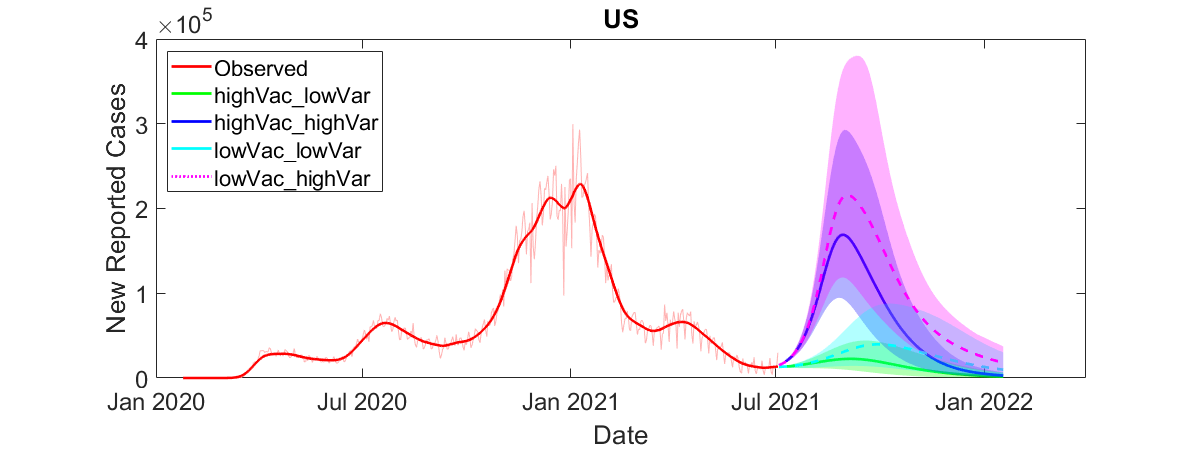

% National Level
cid = popu>-1;
ignore_idx = [51, 52, 53, 55, 56];
cid(ignore_idx) = 0;
figure;    
x_dat = datetime(2020, 1, 23)+ caldays(2:size(data_4, 2));
p_b = plot(x_dat, diff(nansum(data_4(cid, :), 1)), 'r'); hold on; 
p_b.Color = 1 - (1-p_b.Color)*0.3;
plot(x_dat, diff(nansum(data_4_s(cid, :), 1)), 'r', 'LineWidth', 2); hold on; 
xx = diff(squeeze(nansum(net_infec_A(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [nanmin(xx), fliplr(nanmax(xx))]; Y_plot(isinf(Y_plot)) = 0;
plot(x_dat, nanmean(xx, 1), 'g', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','g', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
hold on

xx = diff(squeeze(nansum(net_infec_B(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [nanmin(xx), fliplr(nanmax(xx))]; Y_plot(isinf(Y_plot)) = 0;
plot(x_dat, mean(xx, 1), 'b', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,...
        'facecolor','b', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
xx = diff(squeeze(nansum(net_infec_C(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [nanmin(xx), fliplr(nanmax(xx))]; Y_plot(isinf(Y_plot)) = 0;
plot(x_dat, mean(xx, 1), 'c', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,...
        'facecolor','c', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
hold on
    
xx = diff(squeeze(nansum(net_infec_D(:, cid, :), 2))')';
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2))); xx = fillmissing(xx, "movmean", 3, 2);
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))]; Y_plot(isinf(Y_plot)) = 0;
plot(x_dat, mean(xx, 1), 'm', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,...
        'facecolor','m', ...
        'edgecolor','none', ...
        'facealpha', 0.3);

% Legend entries    
h = zeros(4, 1);
h(1) = plot(NaN,'r', 'LineWidth', 2);
h(2) = plot(NaN,'g', 'LineWidth', 2);
h(3) = plot(NaN,'b', 'LineWidth', 2);
h(4) = plot(NaN, 'c', 'LineWidth', 2);
h(5) = plot(NaN, 'm', 'LineWidth', 2, 'LineStyle', ':');

legend(h, [{'Observed'};...
    scen_names], 'location', 'northwest', 'Interpreter', 'none');
hold off

xlabel('Date')
ylabel('New Reported Cases');
title('US');
set(gca, 'FontSize', 18);
set(gcf,'position',[10,10,1200,450]);

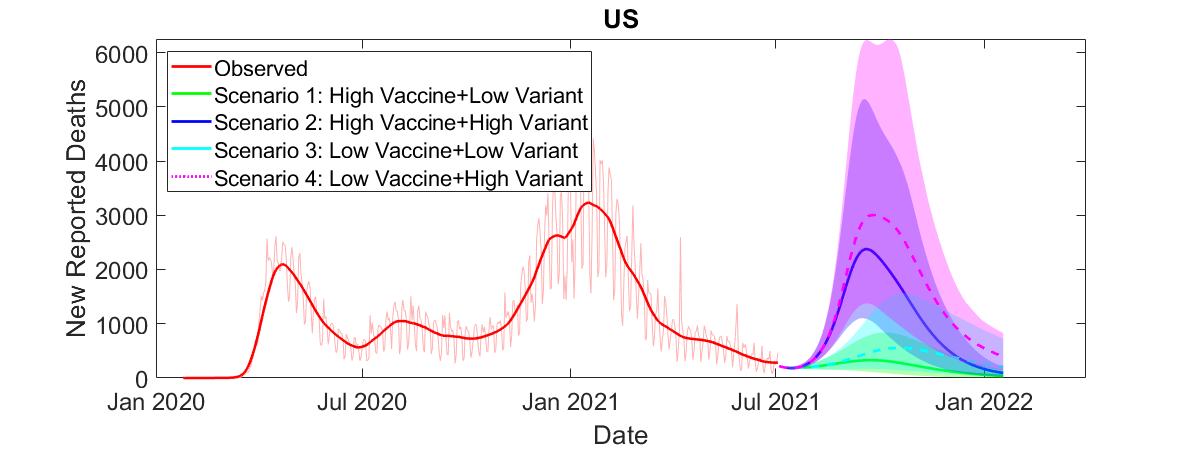


% For deaths
cid = 1:56;
figure;    
x_dat = datetime(2020, 1, 23)+ caldays(2:size(data_4, 2));
p_b = plot(x_dat, diff(nansum(deaths(cid, :), 1)), 'r'); hold on; 
p_b.Color = 1 - (1-p_b.Color)*0.3;
plot(x_dat, diff(nansum(deaths_s(cid, :), 1)), 'r', 'LineWidth', 2); hold on; 
xx = diff(squeeze(nansum(net_death_A(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'g', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','g', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
hold on

xx = diff(squeeze(nansum(net_death_B(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'b', 'LineWidth', 2); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','b', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
xx = diff(squeeze(nansum(net_death_C(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'c', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','c', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    
hold on
    
xx = diff(squeeze(nansum(net_death_D(:, cid, :), 2))')'; nanidx = any(xx<0); xx(:, nanidx) = NaN; xx = fillmissing(xx, "movmean", 3, 2);
x_dat = datetime(2020, 1, 23)+ caldays(size(data_4, 2)+1:(size(data_4, 2)+size(xx, 2)));
X_plot = [x_dat, fliplr(x_dat)];
Y_plot = [min(xx), fliplr(max(xx))];
plot(x_dat, mean(xx, 1), 'm', 'LineWidth', 2, 'LineStyle', '--'); hold on
fill(X_plot, Y_plot , 1,....
        'facecolor','m', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
    

% Legend entries    
h = zeros(4, 1);
h(1) = plot(NaN,'r', 'LineWidth', 2);
h(2) = plot(NaN,'g', 'LineWidth', 2);
h(3) = plot(NaN,'b', 'LineWidth', 2);
h(4) = plot(NaN, 'c', 'LineWidth', 2);
h(5) = plot(NaN, 'm', 'LineWidth', 2, 'LineStyle', ':');

legend(h, 'Observed',...
    'Scenario 1: High Vaccine+Low Variant', 'Scenario 2: High Vaccine+High Variant', 'Scenario 3: Low Vaccine+Low Variant', ...
    'Scenario 4: Low Vaccine+High Variant', 'location', 'northwest');
hold off
xlabel('Date')
ylabel('New Reported Deaths');
title('US');
set(gca, 'FontSize', 18);
set(gcf,'position',[10,10,1200,450]);